# The astrometry function

# in the astronomy & astrophysics toolbox for MATLAB

## Description

The astrometry function is a method in the [SIM class](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/SIM.html) that solve for the astrometry of astronomical images.  The function attempts to find matches between stellar patterns in the image and in a reference catalog, and use it to fit an astrometric solution to the image. The code put emphesize on robustness and to find solutions which are good over the entire field of view. The code is described in Ofek et al. (2018).

This file is accessible through the `manual` package (i.e. `manual.mextractor`).

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O) and Ofek et al. (2018).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

# Examples

Tips: The `astrometry` function has many parameters and for some images/instruments fine tunning of these paramaeters is required. Therefore, we suggest starting by reading the help pages and inspecting the examples.

First, read the FITS images into a [SIM object](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/SIM.html):

S = FITS.read2sim('PTF_20140311*.fits');
S = S(1);

The astrometry command can run on multiple images, but here for simplicity we use a single image.

You can start by extracting sources in the image using (e.g., [mextractor](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/mextractor_Content.html) or `ImUtil.Im.sextractor`). Note that this step is optional and if the catalog is not provided in the SIM object (S), then astrometry will execute mextractor (or sextractor; see input parameters):

S = mextractor(S);

  Set gain to 1
mextractor first pass - Constructing optimal PSF
  Set gain to 1
  No filter found - Use DefFilter
  Estimate images background and std
  Subtract background
mextractor image 1 out of 1
  Filter image number 1 - use 1 filters
    Threshold image and locate local maxima
    Extracting 2094 sources
  Calculate 1st and 2nd moments


mextractor second pass - Source detection and measurments
  Subtract background
mextractor image 1 out of 1
  Filter image number 1 - use 2 filters
    Threshold image and locate local maxima
    Extracting 4249 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)


55 CR flagged in image 1


Now, the catalog of sources identifyied in the image are stored in `S.Cat `and the catalog column names are in` S.Col `and` S.ColCell`.

Next you can execute the `astrometry` function:

[R, S] = astrometry(S,'Flip',[1 -1;1 1; -1 -1]);

The first input argument is alawys a `SIM` object (astrometry is a `SIM` method). The SIM object is followed by pairs of keyword, value. In this case the 'Flip' keyword indicate which coordinates flip should be attempted. Each row in the 'Flip' keyword value (e.g., [1 -1]), indicate how to flip the X and Y coordinates of the image, respectively, prior for matching the image sources with the reference catalog.

By default astrometry will attempt to read the approximate coordinate and scale of the image from the header, however, the use can also provide these parameters directly using the syntax:

[R,S]=astrometry(S,'Scale',1,'RA',3.14,'Dec',0.1); % coordinates in radians

To see a full list of keywords and their default value type

help astrometry

In these examples `astrometry` returns two output arguments. The second output argument is a `SIM` object with the input image (or catalog) and an updated header, with the new WCS values.

 To inspect the image and its WCS you can display the image in ds9:

ds9(S)

The first output argument (R) is a structure array that contains the details of the solution:

R

R =           TranC: [1×1 TranClass]
         rrms1x: 8.9023e-06
         rrms1y: 1.2138e-05
          rrms1: 1.3125e-05
          Nsrc1: 1794
         ResidX: [1794×1 double]
         ResidY: [1794×1 double]
          Resid: [1794×1 double]
         RefMag: [1794×1 double]
       RefColor: [1794×1 double]
           CatX: [1794×1 double]
           CatY: [1794×1 double]
           RefX: [1794×1 double]
           RefY: [1794×1 double]
          FlagG: [1794×1 logical]
           rmsN: 9.5669e-06
         rrmsNx: 6.9054e-06
         rrmsNy: 8.0299e-06
          rrmsN: 8.9782e-06
          NsrcN: 1438
        wmedrms: NaN
    MinAssymErr: 3.0355e-06
       AssymErr: 3.034e-06
       CooUnits: 'deg'
           ParX: [22×1 double]
           ParY: [22×1 double]
        ParErrX: [22×1 double]
        ParErrY: [22×1 double]
         NormXY: 1
     Block_rmsN: [8×4 double]
    Block_rmsXN: [8×4 double]
    Block_rmsYN: [8×4 double]
    Block_NsrcN: [8×4 double]
       ShiftRes: [8×2 double]


This structure contains a lot of meta data on the solution and its quality.

For example 'MinAssymErr' is the asymptotic rms in the units specified in the 'CooUnits' field. You can use this information to verify the quality of the solution:

% show the number of fitted stars in each 512x512 pix sub images
R.Block_NsrcN

ans =     40    67    85    46
    49   108   112    61
    65    95   115    78
    56    67    56    27
     9    43    29     9
     6    14    10    14
    20    42    18     9
    32    66    46    23


% show the robust rms in each subimage
R.Block_rmsN

ans =    7.5878e-06   9.2711e-06   1.0135e-05   1.2554e-05
   1.4786e-05   1.0969e-05   8.9991e-06   1.1441e-05
   6.9189e-06   5.9361e-06   6.4498e-06   8.1823e-06
   5.5538e-06   8.2762e-06   7.6541e-06   9.7943e-06
   7.5869e-06   9.9244e-06   1.5747e-05   6.3091e-06
   3.2223e-06   1.0227e-05     1.37e-05   7.0491e-06
   1.5259e-05   6.6859e-06    6.279e-06   8.2123e-06
   8.8672e-06    8.484e-06   7.3522e-06   8.7693e-06


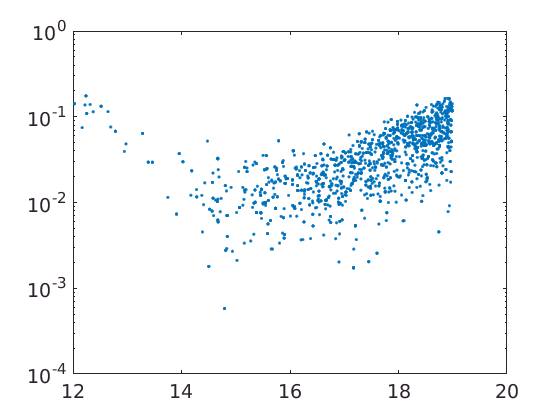

% plot the residuals(arcsec) as a function of magnitude
semilogy(R.RefMag(R.FlagG),R.Resid(R.FlagG).*3600,'.')

Note the 'FlagG' field contains a vector of logical indicating the stars used in the solution (after sigma clipping). By default all the stars vectors (e.g., 'Resid', 'RefMag', 'RefColor', ...) contains all the stars and not only the stars used in the solution.